# PROYECTO 1 - FÓRMULAS DE DERIVACIÓN NUMÉRICA

## EQUIPO N°1

- Mariana Zapata Covarrubias 195111

- Mauricio Verduzco Chavira 195106

- Ricardo Illescas Carrancá 197809

- Alejandro Terrazas Maeshiro 187977

## INTRODUCCIÓN

En el presente proyecto se estudian las diferentes fórmulas de derivación numérica hacia adelante, centrada y hacia atrás en sus diferentes órdenes $O\left(h\right)$, $\left.O{\left(h\right.}^2 \right)$ y $O\left(h^4 \right)$. Para el desarrollo se realizaron pruebas con dos funciones diferentes y se comprararon con la derivada exacta para dilucidar el error.

Antes de empezar definiremos algunos de los conceptos necesarios para el proyecto:

- **Aproximación hacia adelante: **Son aproximaciones de la derivada del tipo $f^{\left(1\right)} \left(x\right)=\frac{f\left(x+h\right)-f\left(x\right)}{h}+O\left(\left(x+h\right)-x\right)\ldotp \ldotp \ldotp$, donde $f$ es la función a evaluar, $x$ es el punto inicial a trabajar y $O\left(\left(x+h\right)-x\right)\;$ es el orden del error. Se conoce cómo derivada hacia adelante debido a que toma datos del tipo xi+h, donde xi es la x dada inicialmente y h es el tamaño de paso positivo que se suma a la x original, es decir, los valores siempre van "hacia adelante".

- **Aproximación centrada: **Son aproximaciones de la derivada del tipo $f^{\left(1\right)} \left(x\right)=\frac{-f\left(x+2h\right)+8f\left(x+h\right)-8f\left(x-h\right)+f\left(x-2h\right)}{12h}+O\left(h^2 \right)$, donde se sigue la misma lógica para las variables. Aquí notamos que se utilizan valores xi+h, así como xi-h, por lo que resulta en un resultado "centrado".

- **Aproximación hacia atrás: **Son aproximaciones de la derivada del tipo $f^{\left(1\right)} \left(x\right)=\frac{f\left(x\right)-f\left(x-h\right)}{h}+O\left(h\right)$. Siguiendo los ejemplos anteriores, este tipo de aproximaciones son lo opuesto a las aproximaciones hacia adelante al tomar datos del tipo xi-h.

Las fórmulas anteriores se refieren a la primera derivada, pero este razonamiento también se cumple en cada caso para la segunda, tercera, hasta n derivada.

### Sobre la primera derivada

- Aproximación hacia adelante de orden ${O\left(h\right):\;f}^{\left(1\right)} \left(x\right)=\frac{f\left(x+h\right)-f\left(x\right)}{h}$

- Aproximación hacia adelante de orden${O\left(h^2 \right):\;f}^{\left(1\right)} \left(x\right)=\frac{-f\left(x+2h\right)+4f\left(x+h\right)-3f\left(x\right)}{2h}$

- Aproximación centrada de orden${O\left(h^2 \right):\;f}^{\left(1\right)} \left(x\right)=\frac{f\left(x+h\right)-f\left(x-h\right)}{2h}$

- Aproximación centrada de orden$O\left(h^4 \right):\;f^{\left(1\right)} \left(x\right)=\frac{-f\left(x+2h\right)+8f\left(x+h\right)-8f\left(x-h\right)+f\left(x+2h\right)}{12h}$

- Aproximación hacia atrás de orden ${O\left(h\right):\;f}^{\left(1\right)} \left(x\right)=\frac{f\left(x\right)-f\left(x-h\right)}{h}$

- Aproximación hacia atrás de orden $O\left(h^2 \right):f^{\left(1\right)} \left(x\right)=\frac{3f\left(x\right)-4f\left(x-h\right)+f\left(x-2h\right)}{2h}$

### Sobre la segunda derivada

- Aproximación hacia adelante de orden ${O\left(h\right):\;f}^{\left(2\right)} \left(x\right)=\frac{f\left(x+2h\right)-2f\left(x+h\right)+f\left(x\right)}{h^2 }$

- Aproximación hacia adelante de orden ${O\left(h^2 \right):\;f}^{\left(2\right)} \left(x\right)=\frac{-f\left(x+3h\right)+4f\left(x+2h\right)-5f\left(x+h\right)+2f\left(x\right)}{h^2 }$

- Aproximación centrada de orden ${O\left(h^2 \right):\;f}^{\left(2\right)} \left(x\right)=\frac{f\left(x+h\right)-2f\left(x\right)+f\left(x-h\right)}{h^2 }$

- Aproximación centrada de orden $O\left(h^4 \right):\;f^{\left(2\right)} \left(x\right)=\frac{-f\left(x+2h\right)+16f\left(x+h\right)-30f\left(x\right)+16f\left(x-h\right)-f\left(x-2h\right)}{12h^2 }$

- Aproximación hacia atrás de orden ${O\left(h\right):\;f}^{\left(2\right)} \left(x\right)=\frac{f\left(x\right)-2f\left(x-h\right)+f\left(x-2h\right)}{h^2 }$

- Aproximación hacia atrás de orden $O\left(h^2 \right):f^{\left(2\right)} \left(x\right)=\frac{2f\left(x\right)-5f\left(x-h\right)+4f\left(x-2h\right)-f\left(x-3h\right)}{h^2 }$

## OBJETIVO

El objetivo de este proyecto es observar los errores que presentan diferentes fórmulas de derivación numérica. Se exploran aproximaciones hacia adelante y hacia atrás de la primera derivada $O\left(h\right)$, aproximaciones centradas de la primera derivada $O\left(h^2 \right)$ y $O\left(h^4 \right)\;$ y de la segunda derivada $O\left(h^2 \right)$. 

## IDENTIFICACIÓN DEL PROBLEMA

Según Steven Chapra, el error numérico total es la suma de los errores de truncamiento y redondeo. Este se genera al utilizar las aproximaciones de las derivadas mencionadas anteriormente y es el objeto principal de las pruebas a realizar a continuación. Antes de seguir, definiremos los conceptos que engloba el error numérico:

- **Error de redondeo:** Se producen al realizar operaciones aritméticas y despreciar las cifras menos significativas. Matlab designa un número definido de bits para cada operación siguiendo el formato de doble precisión IEEE Standard 754 en el que se utilizan ocho bytes (64 bits) para representar números de punto flotante. Debido a esto se introducen errores de redondeo en cada evaluación y, ya que los métodos utilizados contienen iteraciones, en cada una de ellas se suma más y más error resultando en un error de redondeo final grande.

- **Errores de truncación:** Se producen por el uso de una aproximación en lugar de un procedimiento matemático exacto. Implican el recorte de una expansión en serie infinita para hacer posible y práctico el cálculo, o el desecho de los bits menos significativos de una operación aritmética. 

El mayor problema que se nos presenta es la solución de estos dos tipos de errores, ya que los errores de truncamiento disminuyen a medida que aumentan los errores de redondeo. El error de truncamiento se puede reducir al disminuir el paso h, pero esta disminución en el tamaño del paso puede conducir a una cancelación sustractiva o a un aumento en cálculos. El aumento de cálculos es una de las principales causas del error de redondeo. Por lo tanto es necesario encontrar un balance entre estos dos para obtener un resultado óptimo.

## PRUEBAS Y ANÁLISIS

En esta sección se realizarán las pruebas y análisis para comparar el error, la solución y el valor de h dado por las distintas aproximaciones de la primer y segunda derivada.

### FUNCIÓN 1: $f_1 \left(x\right)\;=-0\ldotp 1x^4 -0\ldotp 15x^3 -0\ldotp 5x^2 -0\ldotp 25x+1\ldotp 2$

%   Declaramos la función
f = @(x) -0.1*x.^4 - 0.15*x.^3 -0.5*x.^2 - 0.25*x + 1.2; 

%   Calculamos simbólicamente la primera y segunda derivada para comaprar el resultado con
%   las aproximaciones más adelante
df = matlabFunction(diff(sym(f)));
dftwo = matlabFunction(diff(diff(sym(f))));  
PDF1V = df(.5) 

PDF1V = -0.9125

SDF1V = dftwo(.5) 

SDF1V = -1.7500

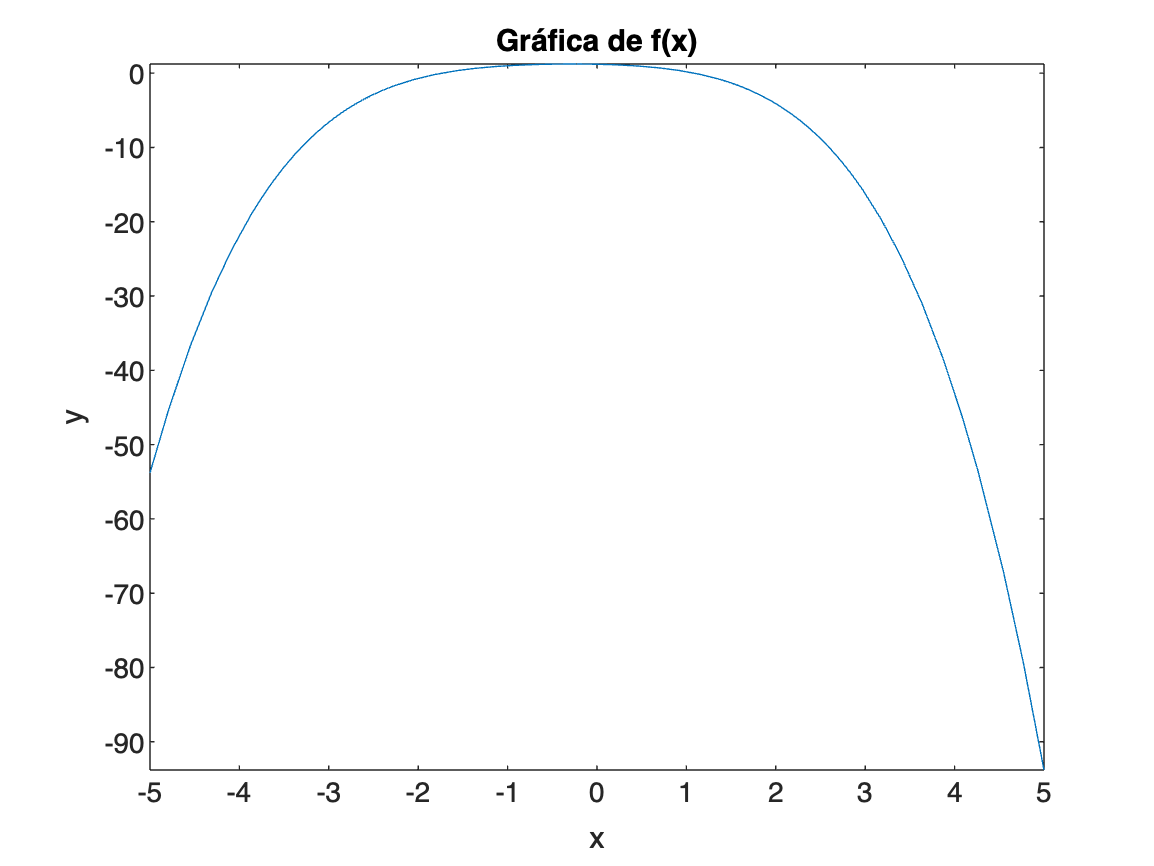


%   Graficamos la función original
fplot(f)
xlabel('x'); ylabel('y')
title('Gráfica de f(x)')

%   Punto en el cual se desea calcular la derivada
x = 0.5;

### Primera Derivada

#### 1.- Aproximación hacia adelante de orden $O\left(h\right)$

[h, dfs, err] = firstFOrd1(f,x) %Ejecutamos nuestra función de derivación

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =    -2.2375   -1.0036   -0.9213   -0.9134   -0.9126   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125


err =     1.3250    0.0911    0.0088    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


plotErrorvsH(err)%Guardamos el error en nuestra función para graficar
MatrizErrores = err;%Guardamos el error en una matriz para analizar más adelante
%Se repite el proceso con todas las funciones

#### 2.- Aproximación hace adelante de orden $O\left(h^2 \right)$

[h, dfs, err] = firstFOrd2(f,x)

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =     0.3875   -0.9049   -0.9124   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125


err =     1.3000    0.0076    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

#### 3.- Aproximación centrada de orden $O\left(h^2 \right)$

[h, dfs, err] = firstDerCOrd2(f,x)

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =    -1.2625   -0.9160   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125


err =     0.3500    0.0035    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

#### 4.- Aproximación centrada de orden $O\left(h^4 \right)$

[h, dfs, err] = firstDerCOrd4(f,x) 

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =    -0.9125   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125


err = 1.0e-07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0055    0.0149    0.3849


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

#### 5.- Aproximación hacia atrás de orden $O\left(h\right)$

[h, dfs, err] = firstDerBOrd1(f,x)

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =    -0.2875   -0.8284   -0.9038   -0.9116   -0.9124   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125


err =     0.6250    0.0841    0.0087    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

#### 6.- Aproximación hacia atrás de orden $O\left(h^2 \right)$

[h, dfs, err] = firstDerBOrd2(f,x)

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =    -0.8125   -0.9061   -0.9124   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125   -0.9125


err =     0.1000    0.0064    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

Gráfica comparativa de las aproximaciones con su Paso v.s. Error de la función 1 en su primera derivada

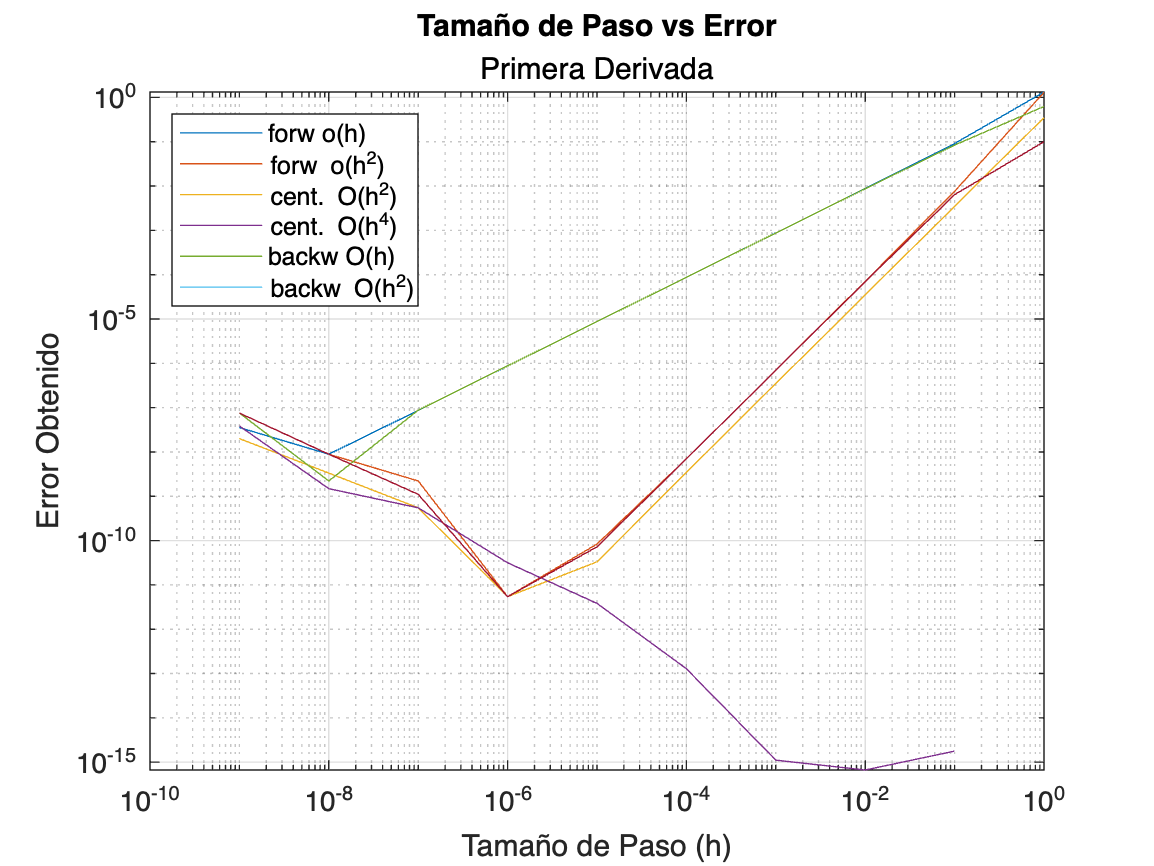

%   Graficamos el error vs el paso de cada aproximación. 
plotErrorvsH(err)
subtitle('Primera Derivada')
legend('forw o(h)','forw o(h^2)','cent. O(h^2)','cent. O(h^4)', ...
    'backw O(h)','backw O(h^2)','Location','NorthWest')
hold off %Se grafica gracias al hold off

MatrizErrores

MatrizErrores =     1.3250    0.0911    0.0088    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
    1.3000    0.0076    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3500    0.0035    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.6250    0.0841    0.0087    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1000    0.0064    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


#### Análisis

%   Generamos un vector de H's
H = getH(10);
%   Encontramos el error mínimo y su índice.
%   Se utiliza la matriz de errores generada y se llama al renglón
%   que contiene los errores obtenidos anteriormente.
%   Gráficamente podemos notar que es la centrada de cuarto orden,
%   es decir, llamamos el cuarto renglón.
[m, idx] = min(MatrizErrores(4,:));
%   Recuperamos el valor de H correspondiente a ese índice para
%   conocer el tamaño de paso óptimo.
h = H(idx)

h = 1

#### Conclusiones

Concluimos que la mejor aproximación para la primera derivada de la primera función se consigue a través de la formula de cuarto orden centrada. En esta logramos encontrar un resultado correcto desde la primera iteración y por esto, el tamaño de paso ideal es h = 1x10^(0) = 1. Esto nos permite afirmar que no siempre resulta intuitivo qué metodo de derivación es el mejor ni mucho menos cuál es el paso óptimo. Por lo anterior resulta evidente la importancia de comparar los resultados para elegir el mejor método posible según la función. 

### Segunda Derivada

#### 1.- Aproximación hacia adelante de orden $O\left(h\right)$

[h, dfs, err] = SecondDerFOrd1(f,x)

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =    -5.2500   -1.9740   -1.7711   -1.7521   -1.7502   -1.7500   -1.7500   -1.7653   -1.1102 -111.0223


err =     3.5000    0.2240    0.0211    0.0021    0.0002    0.0000    0.0000    0.0153    0.6398  109.2723


plotErrorvsH(err)
MatrizErrores = err;

#### 2.- Aproximación hace adelante de orden $O\left(h^2 \right)$

[h, dfs, err] = SecondDerFOrd2(f,x)

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =     0.4500   -1.7280   -1.7498   -1.7500   -1.7500   -1.7500   -1.7504   -1.7542    2.2204 -666.1338


err =     2.2000    0.0220    0.0002    0.0000    0.0000    0.0000    0.0004    0.0042    3.9704  664.3838


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

#### 3.- Aproximación centrada de orden $O\left(h^2 \right)$

[h, dfs, err] = SecondDerCOrd2(f,x)

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =    -1.9500   -1.7520   -1.7500   -1.7500   -1.7500   -1.7500   -1.7499   -1.7431   -1.1102  111.0223


err =     0.2000    0.0020    0.0000    0.0000    0.0000    0.0000    0.0001    0.0069    0.6398  112.7723


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

#### 4.- Aproximación centrada de orden $O\left(h^4 \right)$

[h, dfs, err] = SecondDerCOrd4(f,x) 

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =    -1.7500   -1.7500   -1.7500   -1.7500   -1.7500   -1.7500   -1.7497   -1.7227         0  259.0520


err =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0273    1.7500  260.8020


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

#### 5.- Aproximación hacia atrás de orden $O\left(h\right)$

[h, dfs, err] = SecondDerBOrd1(f,x)

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =    -1.0500   -1.5540   -1.7291   -1.7479   -1.7498   -1.7500   -1.7500   -1.7431   -3.3307 -111.0223


err =     0.7000    0.1960    0.0209    0.0021    0.0002    0.0000    0.0000    0.0069    1.5807  109.2723


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

#### 6.- Aproximación hacia atrás de orden $O\left(h^2 \right)$

[h, dfs, err] = SecondDerBOrd2(f,x)

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =     0.4500   -1.7280   -1.7498   -1.7500   -1.7500   -1.7500   -1.7503   -1.7764  -11.1022 -111.0223


err =     2.2000    0.0220    0.0002    0.0000    0.0000    0.0000    0.0003    0.0264    9.3522  109.2723


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

Gráfica comparativa de las aproximaciones con su Paso v.s. Error de la función 1 en su primera derivada

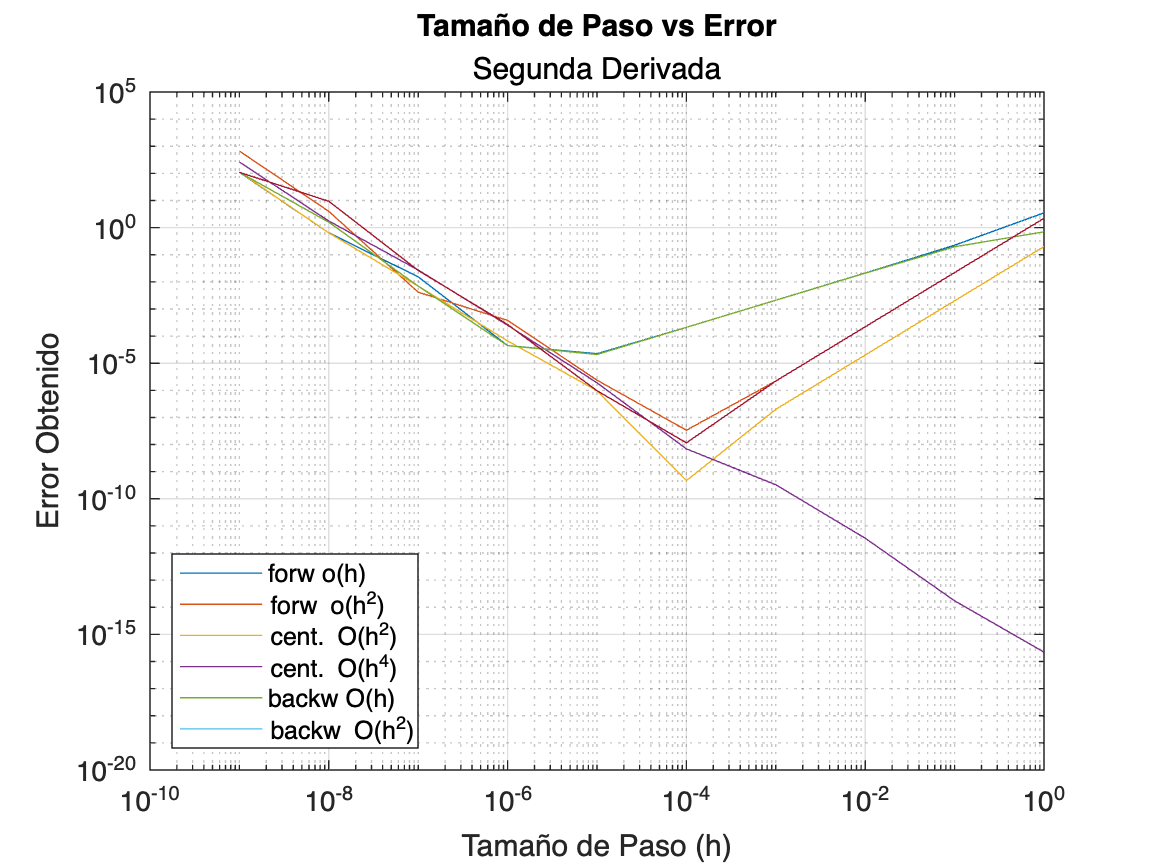

%   Graficamos el error vs el paso de cada aproximación. 
plotErrorvsH(err)
subtitle('Segunda Derivada')
legend('forw o(h)','forw o(h^2)','cent. O(h^2)','cent. O(h^4)', ...
    'backw O(h)','backw O(h^2)','Location','SouthWest')
hold off

MatrizErrores

MatrizErrores =     3.5000    0.2240    0.0211    0.0021    0.0002    0.0000    0.0000    0.0153    0.6398  109.2723
    2.2000    0.0220    0.0002    0.0000    0.0000    0.0000    0.0004    0.0042    3.9704  664.3838
    0.2000    0.0020    0.0000    0.0000    0.0000    0.0000    0.0001    0.0069    0.6398  112.7723
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0273    1.7500  260.8020
    0.7000    0.1960    0.0209    0.0021    0.0002    0.0000    0.0000    0.0069    1.5807  109.2723
    2.2000    0.0220    0.0002    0.0000    0.0000    0.0000    0.0003    0.0264    9.3522  109.2723


#### Análisis

H = getH(10);

[m, idx] = min(MatrizErrores(4,:));

h = H(idx)

h = 1

#### Conclusiones

El resultado de la segunda derivada es el mismo que el de la primera derivada para la primera función. Es decir:

Podemos afirmar que la mejor aproximación para la segunda derivada de la primera función se logra a través de la fórmula de cuarto orden centrada. En esta logramos encontrar un resultado correcto desde la primera iteración y por esto, el tamaño de paso ideal es h = 1x10^(0) = 1. No siempre resulta intuitivo qué metodo de derivación es el mejor ni mucho menos cuál es el paso óptimo, así que resulta evidente la importancia de comparar los resultados para elegir el mejor método posible según la función. 

Lo más valioso que concluir en este ejemplo es que el encontrar la mejor fórmula de derivación y tamaño de paso para la primera derivada, no significa que necesariamente serán las mismas para la segunda. Sin embargo, si no tuvieramos la posibilidad de realizar las pruebas para la segunda derivada, nuestra mejor alternativa sería asumir su parentesco con la primera. 

### FUNCIÓN 2: $f_2 \left(x\right)=\;x^6 -1$

%   Declaramos la función
f = @(x) x.^6 - 1; 

%   Calculamos simbólicamente la primera y segunda derivada para comaprar el resultado con
%   las aproximaciones más adelante
df = matlabFunction(diff(sym(f)));
dftwo = matlabFunction(diff(diff(sym(f))));  
PDF1V = df(.5) 

PDF1V = 0.1875

SDF1V = dftwo(.5) 

SDF1V = 1.8750

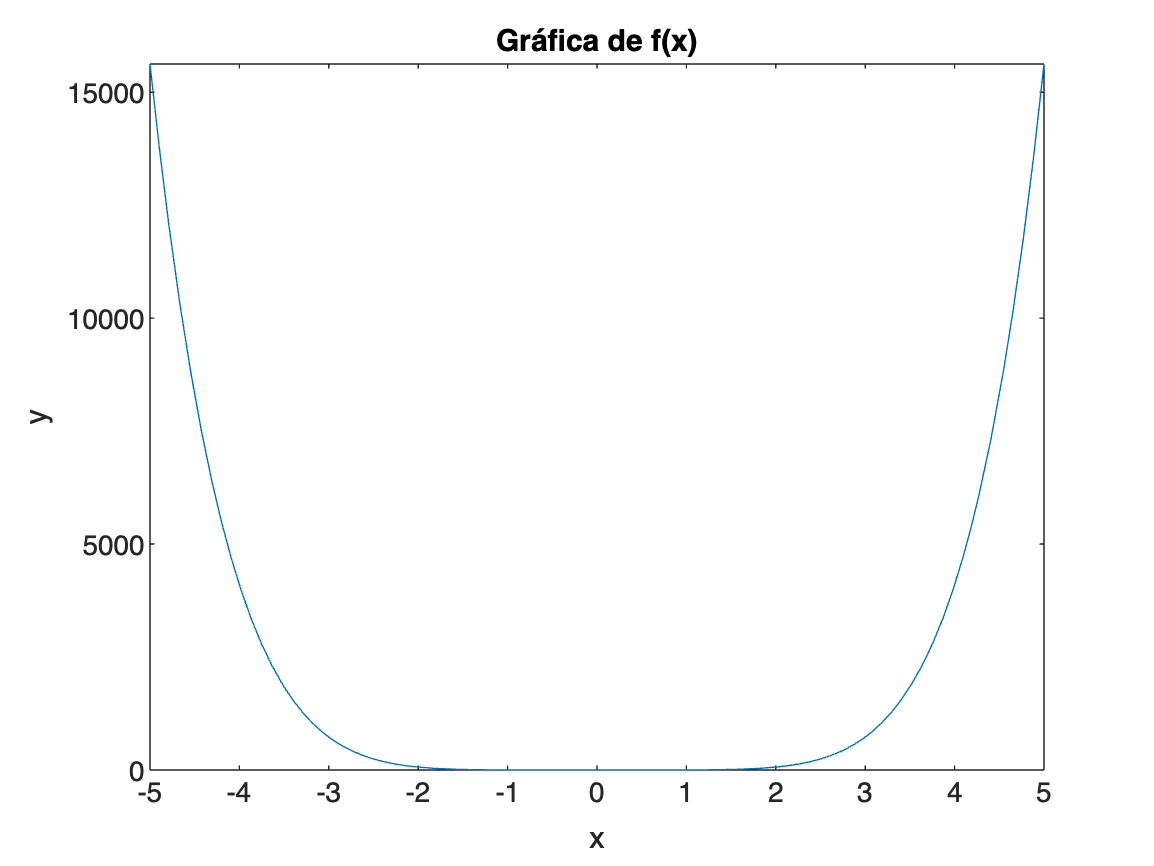


%   Graficamos la función
fplot(f)
xlabel('x'); ylabel('y')
title('Gráfica de f(x)')

%   Punto en el cual se desea calcular la derivada
x = 0.5;

### Primera Derivada

#### 1.- Aproximación hacia adelante de orden $O\left(h\right)$

[h, dfs, err] = firstFOrd1(f,x)

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =    11.3750    0.3103    0.1971    0.1884    0.1876    0.1875    0.1875    0.1875    0.1875    0.1875


err =    11.1875    0.1228    0.0096    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


plotErrorvsH(err)
MatrizErrores = err;

#### 2.- Aproximación hace adelante de orden $O\left(h^2 \right)$

[h, dfs, err] = firstFOrd2(f,x)

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =   -99.3125    0.1105    0.1870    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875


err =    99.5000    0.0770    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

#### 3.- Aproximación centrada de orden $O\left(h^2 \right)$

[h, dfs, err] = firstDerCOrd2(f,x)

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =     5.6875    0.2128    0.1878    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875


err =     5.5000    0.0253    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

#### 4.- Aproximación centrada de orden $O\left(h^4 \right)$

[h, dfs, err] = firstDerCOrd4(f,x) 

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =   -11.8125    0.1863    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875


err =    12.0000    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

#### 5.- Aproximación hacia atrás de orden $O\left(h\right)$

[h, dfs, err] = firstDerBOrd1(f,x)

h = 1×10
    1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs = 1×10
         0    0.1153    0.1784    0.1866    0.1874    0.1875    0.1875    0.1875    0.1875    0.1875


err = 1×10
    0.1875    0.0722    0.0091    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

#### 6.- Aproximación hacia atrás de orden $O\left(h^2 \right)$

[h, dfs, err] = firstDerBOrd2(f,x)

h = 1×10
    1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs = 1×10
    5.6875    0.1561    0.1870    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875


err = 1×10
    5.5000    0.0314    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

Gráfica comparativa de las aproximaciones con su Paso v.s. Error de la función 1 en su primera derivada

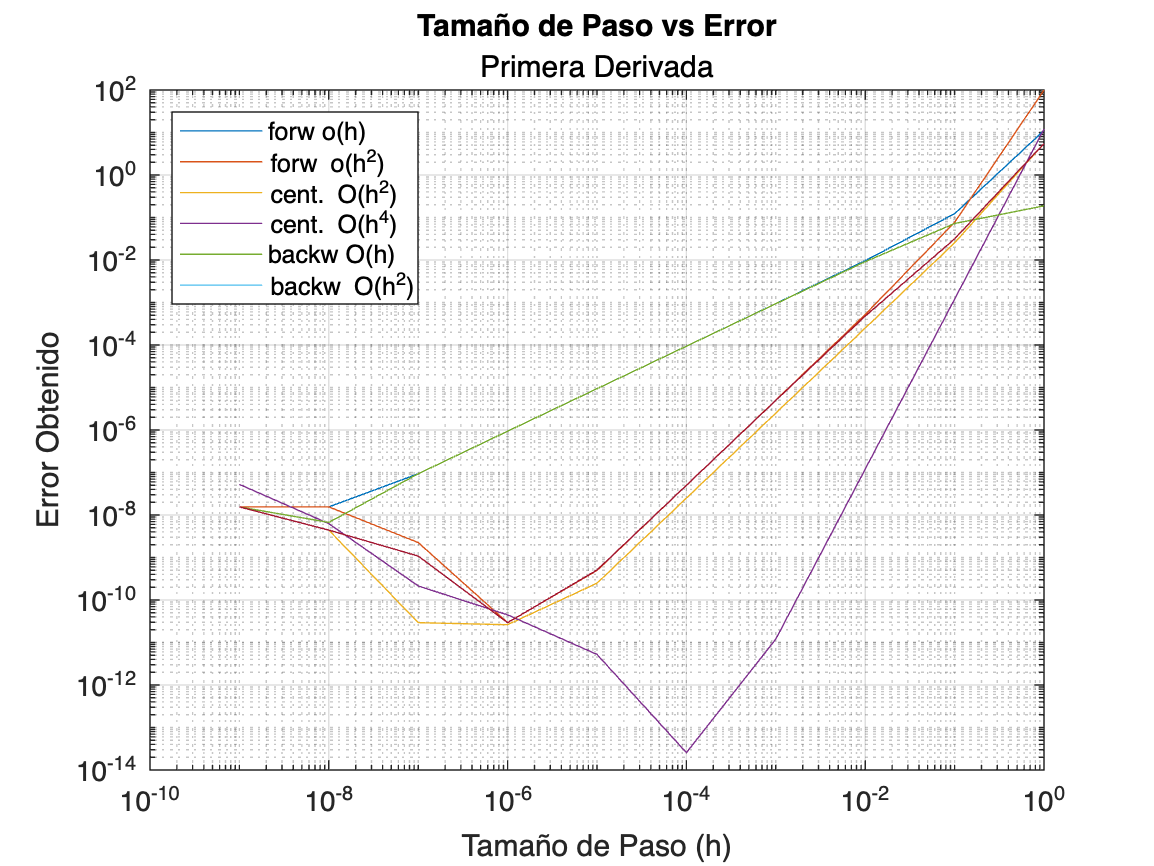

%   Graficamos el error vs el paso de cada aproximación. 
plotErrorvsH(err)
subtitle('Primera Derivada')
legend('forw o(h)','forw o(h^2)','cent. O(h^2)','cent. O(h^4)', ...
    'backw O(h)','backw O(h^2)','Location','NorthWest')
hold off

MatrizErrores

MatrizErrores = 6×10
   11.1875    0.1228    0.0096    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
   99.5000    0.0770    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    5.5000    0.0253    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   12.0000    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1875    0.0722    0.0091    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
    5.5000    0.0314    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


#### Análisis

H = getH(10);

[m, idx] = min(MatrizErrores(4,:));

h = H(idx)

h = 1.0000e-04

#### Conclusiones

En este caso nos encontramos con el mismo tipo de fórmula para encontrar el menor error posible, es decir, la centrada de cuarto orden. En este caso no encontramos un error de '0' desde la primera iteración. De hecho, inicialmente existían errores más pequeños en otras fórmulas, pero conforme cambiamos el tamaño de paso, encontramos que la mejor solución efectivamente se encontró en esta fórmula. Por lo anterior el tamaño de paso óptimo no fue h = 1, sino h = 1x10^-4, pues fue hasta este momento que logramos eliminar el error. A su misma vez, tan pronto disminuimos todavía más el tamaño de paso el error vuelve a aumentar. 

### Segunda Derivada

#### 1.- Aproximación hacia adelante de orden $O\left(h\right)$

[h, dfs, err] = SecondDerFOrd1(f,x)

h = 1×10
    1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs = 1×10
  221.3750    3.9962    2.0303    1.8901    1.8765    1.8752    1.8749    1.8874    1.1102         0


err = 1×10
  219.5000    2.1212    0.1553    0.0151    0.0015    0.0002    0.0001    0.0124    0.7648    1.8750


plotErrorvsH(err)
MatrizErrores = err;

#### 2.- Aproximación hace adelante de orden $O\left(h^2 \right)$

[h, dfs, err] = SecondDerFOrd2(f,x)

h = 1×10
    1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs = 1×10
 -918.6250    0.6422    1.8664    1.8749    1.8750    1.8750    1.8745    1.8652    4.4409         0


err = 1×10
  920.5000    1.2328    0.0086    0.0001    0.0000    0.0000    0.0005    0.0098    2.5659    1.8750


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

#### 3.- Aproximación centrada de orden $O\left(h^2 \right)$

[h, dfs, err] = SecondDerCOrd2(f,x)

h = 1×10
    1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs = 1×10
   11.3750    1.9502    1.8758    1.8750    1.8750    1.8750    1.8751    1.8652    2.2204         0


err = 1×10
    9.5000    0.0752    0.0008    0.0000    0.0000    0.0000    0.0001    0.0098    0.3454    1.8750


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

#### 4.- Aproximación centrada de orden $O\left(h^4 \right)$

[h, dfs, err] = SecondDerCOrd4(f,x) 

h = 1×10
    1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs = 1×10
   -6.1250    1.8742    1.8750    1.8750    1.8750    1.8750    1.8750    1.8670    1.6653   37.0074


err = 1×10
    8.0000    0.0008    0.0000    0.0000    0.0000    0.0000    0.0000    0.0080    0.2097   35.1324


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

#### 5.- Aproximación hacia atrás de orden $O\left(h\right)$

[h, dfs, err] = SecondDerBOrd1(f,x)

h = 1×10
    1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs = 1×10
   11.3750    0.8162    1.7302    1.8601    1.8735    1.8748    1.8749    1.8874    2.2204         0


err = 1×10
    9.5000    1.0588    0.1448    0.0149    0.0015    0.0002    0.0001    0.0124    0.3454    1.8750


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

#### 6.- Aproximación hacia atrás de orden $O\left(h^2 \right)$

[h, dfs, err] = SecondDerBOrd2(f,x)

h = 1×10
    1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs = 1×10
 -198.6250    1.3622    1.8671    1.8749    1.8750    1.8750    1.8748    1.9318         0 -222.0446


err = 1×10
  200.5000    0.5128    0.0079    0.0001    0.0000    0.0000    0.0002    0.0568    1.8750  223.9196


plotErrorvsH(err)
MatrizErrores = [MatrizErrores; err];

Gráfica comparativa de las aproximaciones con su Paso v.s. Error de la función 1 en su primera derivada

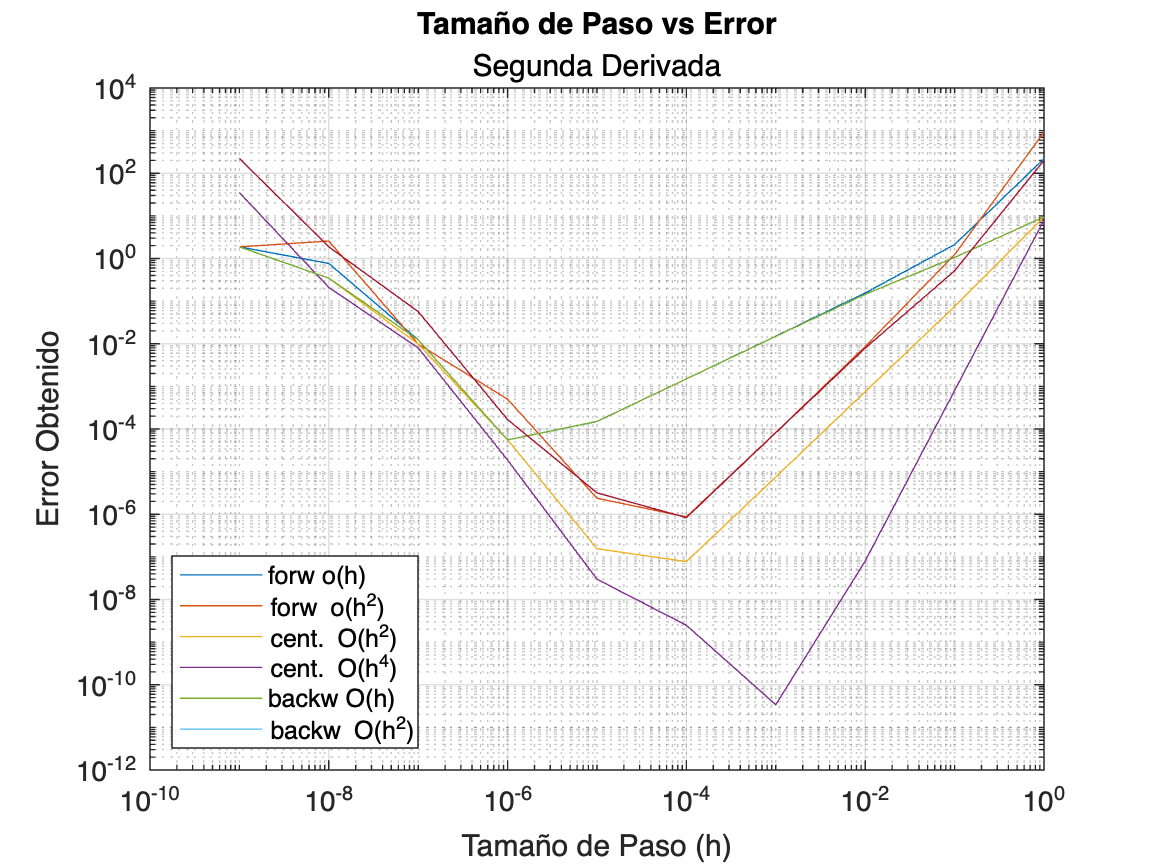

%   Graficamos el error vs el paso de cada aproximación. 
plotErrorvsH(err)
subtitle('Segunda Derivada')
legend('forw o(h)','forw o(h^2)','cent. O(h^2)','cent. O(h^4)', ...
    'backw O(h)','backw O(h^2)','Location','SouthWest')
hold off

MatrizErrores

MatrizErrores = 6×10
  219.5000    2.1212    0.1553    0.0151    0.0015    0.0002    0.0001    0.0124    0.7648    1.8750
  920.5000    1.2328    0.0086    0.0001    0.0000    0.0000    0.0005    0.0098    2.5659    1.8750
    9.5000    0.0752    0.0008    0.0000    0.0000    0.0000    0.0001    0.0098    0.3454    1.8750
    8.0000    0.0008    0.0000    0.0000    0.0000    0.0000    0.0000    0.0080    0.2097   35.1324
    9.5000    1.0588    0.1448    0.0149    0.0015    0.0002    0.0001    0.0124    0.3454    1.8750
  200.5000    0.5128    0.0079    0.0001    0.0000    0.0000    0.0002    0.0568    1.8750  223.9196


#### Análisis

H = getH(10);

[m, idx] = min(MatrizErrores(4,:));

h = H(idx)

h = 1.0000e-03

#### Conclusiones

Finalmente la útlima formula de dervación resultó ser la misma que en los últimos tres casos. Similarmente al caso de la primera derivada de la segunda función, no encontramos el valor de la derivada desde la primera iteración sino hasta la tercera. En este caso el menor error en la primera iteración sí se encontraba en esta fórmula con una h = 1x10^-3. 

Debido a este resultado no podemos afirmar que el tamaño de paso para la primera derivada sería el mismo para la segunda. 

## CONCLUSIONES GENERALES

Al final de este proyecto descubrimos que es importante conocer las distintas fórmulas de derivación numérica (para adelante, centrada y para atrás) y los órdenes de los errores así cómo su tipo (de redondeo y de truncamiento). Estas características son importantes al momento de tomar una decisión porque no siempre será la misma fórmula y no siempre tendremos el mismo tamaño de paso. No podemos generalizar que siempre la fórmula centrada de cuarto orden será la mejor fórmula, ni que el tamaño de paso siempre será 'x' o 'y'. En fin, este tipo de experimentación de pruebas y análisis se debería de ejecutar para una función antes de "derivarla arbitrariamente" para encontrar el mínimo error óptimo. 

En otras palabras, gracias al presente proyecto logramos identificar los distintos tipos de errores relacionados con distintas fórmulas y especialmente a analizarlo para tomar decisiones.

## REFERENCIAS

S. Chapra and R. Canale, “Numerical Methods for Engineers Sixth Edition,” May 2010. Recuperado el 20 de enero de 2023.

Ascher & Greif, “A First Course in Numerical Methods”, SIAM, 2011. Chapter 14 – Numerical Differentiation. Recuperado el 20 de enero de 2023.

## ANEXOS

### FUNCIONES

#### Primera Derivada

function [h, dfs, err] = firstDerBOrd1(f, x)
n = 10; % Se establece n=10 para obtener 10 valores de h
df = matlabFunction(diff(sym(f))); %Se obtiene la primera derivada de la función
                                   %con las herramientas de MATLAB
h = getH(n); % Generamos el vector de los valores de n
dfs = (f(x) - f(x - h)) ./ h; %Calculamos la derivada numéricamente
err = abs(df(x) - dfs); %Calculamos el error comparando la derivada numérica con
                        %la calculada con las herramientas de MATLAB
end
% First Derivative Backward Order 2
function [h, dfs, err] = firstDerBOrd2(f, x) 
n = 10; % Se establece n=10 para obtener 10 valores de h
df = matlabFunction(diff(sym(f))); %Se obtiene la primera derivada de la función
                                   %con las herramientas de MATLAB
h = getH(n); % Generamos el vector de los valores de n
dfs = (3 .* f(x) - 4 .* f(x - h) + f(x - 2 .* h)) ./ (2 .* h); 
%Calculamos la derivada numéricamente
err = abs(df(x) - dfs); %Calculamos el error comparando la derivada numérica con 
                        %la calculada con las herramientas de MATLAB
end
% First Derivative Central Order 2
function [h, dfs, err] = firstDerCOrd2(f, x)
n = 10; % Se establece n=10 para obtener 10 valores de h
df = matlabFunction(diff(sym(f))); %Se obtiene la primera derivada de la función
                                   %con las herramientas de MATLAB
h = getH(n); % Generamos el vector de los valores de n
dfs = (f(x + h) - f(x - h)) ./ (2 .* h); %Calculamos la derivada numéricamente
err = abs(df(x) - dfs); %Calculamos el error comparando la derivada numérica con 
                        %la calculada con las herramientas de MATLAB
end
% First Derivative Central Order 4
function [h, dfs, err] = firstDerCOrd4(f, x)
n = 10; % Se establece n=10 para obtener 10 valores de h
df = matlabFunction(diff(sym(f))); %Se obtiene la primera derivada de la función
                                   %con las herramientas de MATLAB
h = getH(n); % Generamos el vector de los valores de n
dfs = (-f(x + 2*h) + 8 .* f(x + h) - 8 .* f(x - h) + f(x - 2*h)) ./ (12 .* h);
% Calculamos la derivada numéricamente
err = abs(df(x) - dfs); %Calculamos el error comparando la derivada numérica con 
                        %la calculada con las herramientas de MATLAB
end
% First Derivative Forward Order 1
function [h, dfs, err] = firstFOrd1(f, x)
n = 10; % Se establece n=10 para obtener 10 valores de h
df = matlabFunction(diff(sym(f))); %Se obtiene la primera derivada de la función
                                   %con las herramientas de MATLAB
h = getH(n); % Generamos el vector de los valores de n
dfs = (f(x + h) - f(x)) ./ h; %Calculamos la derivada numéricamente
err = abs(df(x) - dfs); %Calculamos el error comparando la derivada numérica con 
                        %la calculada con las herramientas de MATLAB
end
% First Derivative Forward Order 2
function [h, dfs, err] = firstFOrd2(f, x)
n = 10; % Se establece n=10 para obtener 10 valores de h
df = matlabFunction(diff(sym(f))); %Se obtiene la primera derivada de la función
                                   %con las herramientas de MATLAB
h = getH(n); % Generamos el vector de los valores de n
dfs = (-f(x + 2*h) + 4 .* f(x + h) - 3 .* f(x)) ./ (2 .* h); 
%Calculamos la derivada numéricamente
err = abs(df(x) - dfs); %Calculamos el error comparando la derivada numérica con 
                        %la calculada con las herramientas de MATLAB
end

#### Segunda Derivada

function [h,dfs,err] = SecondDerBOrd1(f,x)
    n=10; % Se establece n=10 para obtener 10 valores de h
    df=matlabFunction(diff(diff(sym(f))));
    % Obtenemos la segunda derivada de la función con las herramientas de
    % matlab y la dejamos como otra función
    h=getH(n); % Generamos el vector de los valores de n
    dfs=(f(x)-2.*f(x-h)+f(x-2*h))./(h.^2); 
    % Copiamos la función de la bibliografía
    err=abs(df(x)-dfs); % Calculamos el error comparando la aproximación con  
                        % el cálculo de la segunda derivada de matlab
end
%
function [h,dfs,err] = SecondDerBOrd2(f,x)
    n=10; % Se establece n=10 para obtener 10 valores de h
    df=matlabFunction(diff(diff(sym(f))));
    % Obtenemos la segunda derivada de la función con las herramientas de
    % matlab y la dejamos como otra función
    h=getH(n); % Generamos el vector de los valores de n
    dfs=(2.*f(x)-5.*f(x-h)+4.*f(x-2*h)-f(x-3*h))./(h.^2); % Copiamos la función de 
                                                          % la bibliografía
    err=abs(df(x)-dfs); % Calculamos el error comparando la aproximación con el 
                        % cálculo de la segunda derivada de matlab
end
%
function [h,dfs,err] = SecondDerCOrd2(f,x)
    n=10; % Se establece n=10 para obtener 10 valores de h
    df=matlabFunction(diff(diff(sym(f)))); 
    % Obtenemos la segunda derivada de la función con las herramientas de
    % matlab y la dejamos como otra función
    h=getH(n); % Generamos el vector de los valores de n
    dfs=(f(x+h)-2*f(x)+f(x-h))./(h.^2); % Copiamos la función de la bibliografía
    err=abs(df(x)-dfs); % Calculamos el error comparando la aproximación con el  
                        % cálculo de la segunda derivada de matlab 
end
%
function [h,dfs,err] = SecondDerCOrd4(f,x)
    n=10; % Se establece n=10 para obtener 10 valores de h
    df=matlabFunction(diff(diff(sym(f))));
    % Obtenemos la segunda derivada de la función con las herramientas de
    % matlab y la dejamos como otra función
    h=getH(n); % Generamos el vector de los valores de n
    dfs=(-f(x+2*h)+16.*f(x+h)-30.*f(x)+16.*f(x-h)-f(x-2*h))./(12.*h.^2); 
    % Copiamos la función de la bibliografía
    err=abs(df(x)-dfs); % Calculamos el error comparando la aproximación con  
                        % el cálculo de la segunda derivada de matlab
end
%
function [h,dfs,err] = SecondDerFOrd1(f,x)
    n=10; % Se establece n=10 para obtener 10 valores de h
    df=matlabFunction(diff(diff(sym(f)))); 
    % Obtenemos la segunda derivada de la función con las herramientas de
    % matlab y la dejamos como otra función
    h=getH(n); % Generamos el vector de los valores de n
    dfs=(f(x+2*h)-2.*f(x+h)+f(x))./(h.^2); 
    % Copiamos la función de la bibliografía
    err=abs(df(x)-dfs); % Calculamos el error comparando la aproximación con  
                        % el cálculo de la segunda derivada de matlab
end
%
function [h, dfs, err] = SecondDerFOrd2(f, x)
    n=10; % Se establece n=10 para obtener 10 valores de h
    df=matlabFunction(diff(diff(sym(f))));
    % Obtenemos la segunda derivada de la función con las herramientas de
    % matlab y la dejamos como otra función
    h=getH(n); % Generamos el vector de los valores de n
    dfs=(-f(x+3*h)+4.*f(x+2*h)-5.*f(x+h)+2.*f(x))./(h.^2); 
    % Copiamos la función de la bibliografía
    err=abs(df(x)-dfs); % Calculamos el error comparando la aproximación con   
                        % el cálculo de la segunda derivada de matlab
end